# definition of variables

clc;
clear;

m=1; %mass
l=1; %length
g=9.81; %gravity
J=m*l*l/3; %moment of inertia for rod with axis passing through one end
R=1.22;
L=5.13;
Km=0.363;
Kt=0.31;
n=50;
max_time=200;
theta_desired=0.5;

global time_prior ...
        error_theta_prior error_theta_dot_prior ...
        integral_theta integral_theta_dot;
time_prior = 0; 
integral_theta=0;
integral_theta_dot=0;
error_theta_prior=0;
error_theta_dot_prior=0;

## ode45 and plotting

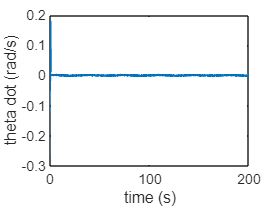

tspan=[0 max_time];
x_init=transpose([theta_desired 0 0]); %initial value of state space
[t, x]=ode45(@(t, x) odefcn(t, x, theta_desired), tspan, x_init);

y_tht_dot = x(:, 2); %angular velocity
y_tht = x(:, 1); %angle
%y_i = x(:, 3); %current
%y_tau_motor = n*Kt*y_i;

%graph_tau_motor=plot(t, y_tau_motor);
%xlabel('time (s)');
%ylabel('motor torque (N.m)');
%set(graph_tau_motor, 'linewidth', 1.5);

%graph_current=plot(t, y_i);
%xlabel('time (s)');
%ylabel('current (amp)');
%set(graph_current, 'linewidth', 1.5);

graph_angular_velocity=plot(t, y_tht_dot);
xlabel('time (s)');
ylabel('theta dot (rad/s)');
set(graph_angular_velocity, 'linewidth', 1.5);

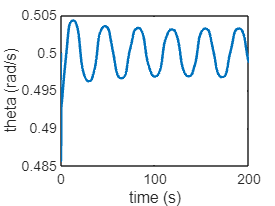


graph_angular_displacement=plot(t, y_tht);
xlabel('time (s)');
ylabel('theta (rad/s)');
set(graph_angular_displacement, 'linewidth', 1.5);

%ylim([0 inf]);


## function definitions

function dxdt = odefcn(t, x, theta_desired)
    m=1; %mass
    l=1; %length
    g=9.81; %gravity
    J=m*l*l/3; %moment of inertia for rod with axis passing through one end
    R=1.22;
    L=5.13;
    Km=0.363;
    Kt=0.31;
    n=50;
    global time_prior error_theta_dot_prior error_theta_prior;

    %the following is our state space definition
    theta=x(1, 1); %theta_actual
    theta_dot=x(2, 1); %derivative of theta
    i=x(3, 1); %current
    
    tau_disturbance=sin(t);
    error_theta=theta_desired-theta;
    error_dot_theta=(error_theta-error_theta_prior);
    theta_dot_desired=control_theta(t, error_theta, time_prior, error_dot_theta);
        
    error_theta_dot=theta_dot_desired-theta_dot;
    error_dot_theta_dot=error_theta_dot-error_theta_dot_prior;
    V=control_theta_dot(t, error_theta_dot, time_prior, error_dot_theta_dot); %voltage
    %clipping of voltage
    V=clip(V, 10, -10);
           
    error_theta_prior=error_theta;
    error_theta_dot_prior=error_theta_dot;
    time_prior=t;

    
    %differential equations for ode45
    dxdt=zeros(3, 1);
    dxdt(1, 1)=theta_dot;
    dxdt(2, 1)=(n*Kt/J)*((tau_disturbance/(n*Kt))+i-(m*g*l*cos(theta))/(2*n*Kt));
    dxdt(3, 1)=(V-(R*i)-(Km*n*theta_dot)/L);
end

function u = control_theta(t, error, time_prior, error_dot)
    %PID gains
    kp=11; %21
    ki=3; %10
    kd=850; %60
    bias=0; %0.32 for theta_desired=0.5
    
    global integral_theta;
    integral_theta=integral_theta+ki*error*(t-time_prior);
    u=kp*error+integral_theta+kd*error_dot+bias;
end

function u = control_theta_dot(t, error, time_prior, error_dot)
    %PID gains
    kp=40; %21
    ki=5; %10
    kd=60; %60
    bias=0; %0.32 for theta_desired=0.5
    
    global integral_theta_dot;
    integral_theta_dot=integral_theta_dot+ki*error*(t-time_prior);
    u=kp*error+integral_theta_dot+kd*error_dot*1000+bias;
end

function val = clip(val, upper_bound, lower_bound)
   if val>upper_bound
        val=upper_bound;
    end
    if val<lower_bound
        val=lower_bound;
    end 
end